# Example 5.12: Hougen-Watson Model with Ridge Penalty

Note: this script reproduces Example 5.12 (Section 5.4) of **Statistics for Chemical Engineers**: adding a ridge penalty to the SSE of the Hougen-Watson model. Victor Z UW-Madison, 2020 regularization for Hougen-Watson equation [https://www.mathworks.com/help/stats/rsmdemo.html](https://www.mathworks.com/help/stats/rsmdemo.html)

clc;  clear all;  close all hidden; 
format bank

% S = load('reaction');
% X = S.reactants % experimental reactant concentrations
% y = S.rate % experimental reaction rates
% beta = S.beta % guess for parameters

data=load('Data/hougenwatson.dat');
X=data(:,1:3); %partial pressures
y=data(:,4);   % reaction rate

data=[X,y];
save 'Data/hougenwatson.dat' data -ascii

## Data and reference values

best guess for parameters

beta = [1.0000e+00
        5.0000e-02
        2.0000e-02
        1.0000e-01
        2.0000e+00];

[n,m]=size(X);


% prior variance
sigma=1;

## Regularized SSE function

span parameter

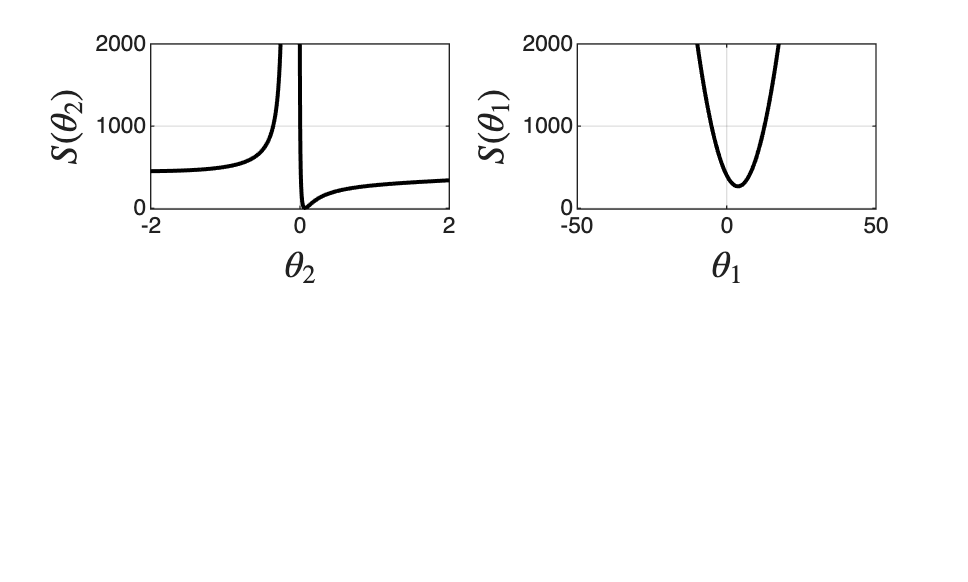

nmesh = 1000;
bv = linspace(-2,2,nmesh); 
betav=beta;

for j=1:nmesh
    betav(2)=bv(j);
    for i=1:n
     yhat(i)=myf(betav,X(i,:));
     e(i)=0.5*(y(i)-yhat(i))^2 + (0.5/sigma)*norm(betav-beta)^2;
    end
    SS(j)=sum(e);
end

figure(1)
subplot(2,2,1)
plot(bv,SS,'black','LineWidth',1.5)
grid on
xlabel('$\theta_2$','Interpreter','latex','FontSize',14)
ylabel('$S(\theta_2)$','Interpreter','latex','FontSize',14)
axis([-2 2, -10, 2000])

% span another param
bv = linspace(-50,50,nmesh); 
for j=1:nmesh
    betav(1)=bv(j);
    for i=1:n
     yhat(i)=myf(betav,X(i,:));
     e(i)=0.5*(y(i)-yhat(i))^2+ (0.5/sigma)*norm(betav-beta)^2;
    end
    SS(j)=sum(e);
end

figure(1)
subplot(2,2,2)
plot(bv,SS,'black','LineWidth',1.5)
grid on
xlabel('$\theta_1$','Interpreter','latex','FontSize',14)
ylabel('$S(\theta_1)$','Interpreter','latex','FontSize',14)
axis([-50, 50, -10, 2000])
print -depsc ch5_hougen_span_reg.eps


function y=myf(b,x)

b1=b(1);
b2=b(2);
b3=b(3);
b4=b(4);
b5=b(5);
x1=x(1);
x2=x(2);
x3=x(3);

y=(b1*x2-x3/b5)/(1+b2*x1+b3*x2+b4*x3);

end

## Note

As in the book, the penalty makes the minimum sharper but does not remove the non-physical regions, so numerical issues may remain.